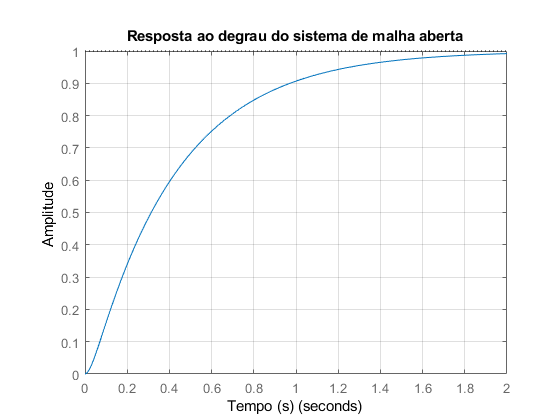

% Parâmetros do sistema
Kp = 8.9951;     % Ganho proporcional
Ki = 39.1826;        % Ganho integral
Kd = 0.8599;        % Ganho derivativo

% Função de transferência da planta
num = 83.2;
den = [1 36.44 83.2];
plant = tf(num, den);

% Tempo de simulacao
t = 0:0.01:2;
% Simulação de um step
step(plant, t);
% Configurações do gráfico
title('Resposta ao degrau do sistema de malha aberta');
xlabel('Tempo (s)');
ylabel('Amplitude');
grid on;

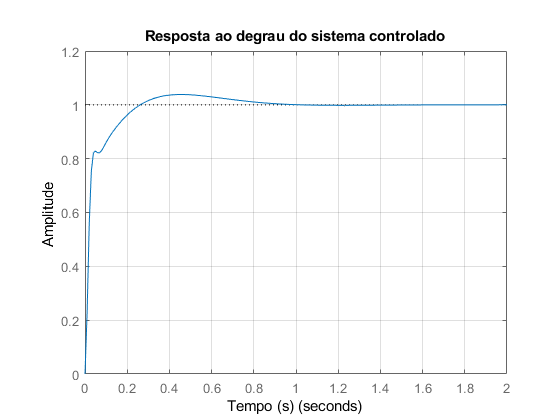


% Controlador PID
pidController =tf([Kd Kp Ki],[0.01 1 0]) ;% Criando o controlador PID

% Sistema em malha fechada
sys = feedback(pidController*plant, 1);

% Simulação de um step
step(sys, t);

% Configurações do gráfico
title('Resposta ao degrau do sistema controlado');
xlabel('Tempo (s)');
ylabel('Amplitude');
grid on;